clear all
close all

ch_dwnsmpl=5;                                       %give the downsampling rate
ch_rate=2000; ch_rate=ch_rate/ch_dwnsmpl;           %give the silicon probe sampling rate (in Hz)
th.nbins = 40; th.binsize = 360/th.nbins;                                  %give the number of theta bins 
gm.nbins = 20; gm.binsize = 360/gm.nbins;
binscale=(th.binsize/2):(th.binsize):(360-(th.binsize/2));
thbins=(th.binsize/2):th.binsize:(360-(th.binsize/2));
gmbins=(gm.binsize/2):gm.binsize:(360-(gm.binsize/2));
NGF_theta=readtable('NGF_theta_midgamma_coupling.xlsx');

## Plotting

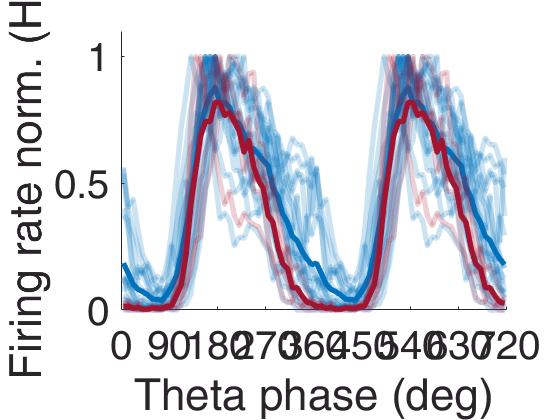

% Theta coupling for all identified (red) and putative (blue) neurogliaform cells
figure;
for je=6:23
    NGFput_thetaNorm(je-5,:) = NGF_theta{je, 3:42}./max(NGF_theta{je,3:42}); %theta coupling of all spikes
end
meanThetaPut=mean(NGFput_thetaNorm);
line ([thbins thbins+360], [meanThetaPut meanThetaPut], 'LineWidth', 4, 'Color', [0 0.4470 0.7410]);
hold on
for je=1:18
    lh=plot([thbins thbins+360], repmat(NGFput_thetaNorm(je,:),1,2), 'linewidth', 4, 'Color', [0 0.4470 0.7410]);
    lh.Color=[0 0.4470 0.7410,0.2];
    hold on
end

%identified neurogliaform (coupling normalized)
for je=1:5%theta coupling of all spikes
    NGF_thetaNorm(je,:) = NGF_theta{je, 3:42}./max(NGF_theta{je,3:42});
end
meanThetaId=mean(NGF_thetaNorm);
line ([thbins thbins+360], [meanThetaId meanThetaId], 'LineWidth', 4, 'Color', [0.6350 0.0780 0.1840]); % mean
hold on
for je=1:5
    lh=plot([thbins thbins+360], repmat(NGF_thetaNorm(je,:),1,2), 'LineWidth', 4); % all individual lines
    lh.Color=[0.6350,0.0780,0.1840,0.2];
    hold on
end


x=[0:1:720]; y=(cosd(x+180)+1).*0.5; 
% line (x,y, 'Color', 'k', 'LineWidth', 2) % theta
%y=[0:0.1:1];
%axis ([0 720 0 1]);
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',30)
xlabel ('Theta phase (deg)'); ylabel ('Firing rate norm. (Hz)')
%pozi=get(gca,'Position'); pozi=[pozi(1) pozi(2) 1.2*pozi(3) 1.2*pozi(4)]; set(gca,'Position',pozi)

xlim([0 720])
ylim([0 1.1])
set(gca, 'Clipping', 'off')    

% Theta coupling for all identified (red) and putative (blue) neurogliaform cells !!Firing rate
figure;
for je=6:23
    NGFput_thetaNorm(je-5,:) = NGF_theta{je+48, 3:22}./max(NGF_theta{je+48,3:22}); %theta coupling of FR
end
meanThetaPut=mean(NGFput_thetaNorm);
line ([gmbins gmbins+360], [meanThetaPut meanThetaPut], 'LineWidth', 4, 'Color', [0 0.4470 0.7410]);
hold on
for je=1:18
    lh=plot([gmbins gmbins+360], repmat(NGFput_thetaNorm(je,:),1,2), 'linewidth', 4, 'Color', [0 0.4470 0.7410]);
    lh.Color=[0 0.4470 0.7410,0.2];
    hold on
end

%identified neurogliaform (coupling normalized)
for je=1:5%theta coupling of FR
    NGF_thetaNorm(je,:) = NGF_theta{je+48, 3:22}./max(NGF_theta{je+48,3:22});
end
meanThetaId=mean(NGF_thetaNorm);
line ([gmbins gmbins+360], [meanThetaId meanThetaId], 'LineWidth', 4, 'Color', [0.6350 0.0780 0.1840]); % mean
hold on
for je=1:5
    lh=plot([gmbins gmbins+360], repmat(NGF_thetaNorm(je,:),1,2), 'LineWidth', 4); % all individual lines
    lh.Color=[0.6350,0.0780,0.1840,0.2];
    hold on
end


x=[0:1:720]; y=(cosd(x+180)+1).*0.5; 
% line (x,y, 'Color', 'k', 'LineWidth', 2) % theta
%y=[0:0.1:1];
%axis ([0 720 0 1]);
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',30)
xlabel ('Theta phase (deg)'); ylabel ('Firing rate norm. (Hz)')
%pozi=get(gca,'Position'); pozi=[pozi(1) pozi(2) 1.2*pozi(3) 1.2*pozi(4)]; set(gca,'Position',pozi)

xlim([0 720])
ylim([0 1.1])
set(gca, 'Clipping', 'off')   

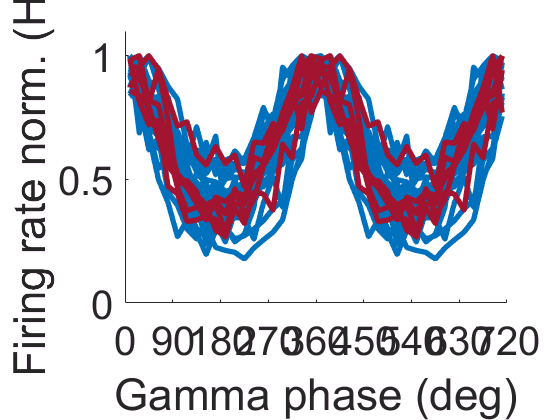

% Mid-gamma coupling for all identified (red) and putative (blue) neurogliaform cells
figure;
for je=6:23
    NGFput_gammaNorm(je-5,:) = NGF_theta{je+24, 45:64}./max(NGF_theta{je+24,45:64}); %gamma couplinf of selected spikes
end
meanGammaPut=mean(NGFput_gammaNorm);
line ([gmbins gmbins+360], [meanGammaPut meanGammaPut], 'LineWidth', 4, 'Color', [0 0.4470 0.7410]);
hold on
for je=1:18
    lh=plot([gmbins gmbins+360], repmat(NGFput_gammaNorm(je,:),1,2), 'linewidth', 4, 'Color', [0 0.4470 0.7410]);
    lh.Color=[0 0.4470 0.7410,0.2];
    hold on
end

for je=1:5
    NGF_gammaNorm(je,:) = NGF_theta{je+24, 45:64}./max(NGF_theta{je+24,45:64});
end
meanGammaId=mean(NGF_gammaNorm);
line ([gmbins gmbins+360], [meanGammaId meanGammaId], 'LineWidth', 4, 'Color', [0.6350 0.0780 0.1840]);
hold on
for je=1:5
    lh=plot([gmbins gmbins+360], repmat(NGF_gammaNorm(je,:),1,2), 'linewidth', 4, 'Color', [0.6350 0.0780 0.1840]);
    lh.Color=[0.6350 0.0780 0.1840,0.2];
    hold on
end


%x=[0:1:720]; y=(cosd(x+180)+1).*0.5; 
% line (x,y, 'Color', 'k', 'LineWidth', 2) % theta
%y=[0:0.1:1];
%axis ([0 720 0 1]);
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',30)
xlabel ('Gamma phase (deg)'); ylabel ('Firing rate norm.')
%pozi=get(gca,'Position'); pozi=[pozi(1) pozi(2) 1.2*pozi(3) 1.2*pozi(4)]; set(gca,'Position',pozi)

xlim([0 720])
ylim([0 1.1])
set(gca, 'Clipping', 'off')

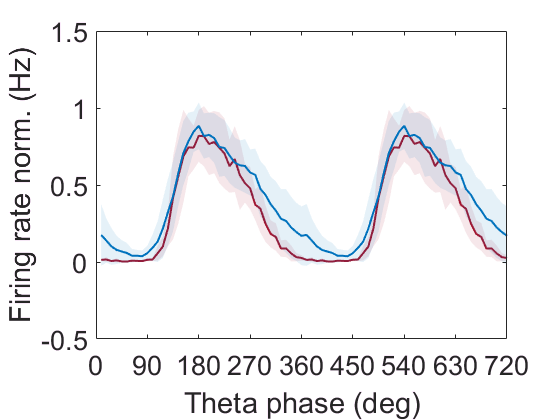

figure;
for je=1:5
    NGF_thetaNorm(je,:) = NGF_theta{je+24, 3:42}./max(NGF_theta{je+24,3:42});
end

stdshade([NGF_thetaNorm NGF_thetaNorm], 0.1, [0.6350 0.0780 0.1840]);

hold on

for je=6:23
    NGFput_thetaNorm(je-5,:) = NGF_theta{je+24, 3:42}./max(NGF_theta{je+24,3:42});
end

stdshade([NGFput_thetaNorm NGFput_thetaNorm], 0.1, [0 0.4470 0.7410]);
xlabel ('Theta phase (deg)'); ylabel ('Firing rate norm. (Hz)')
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',20)
xticks(0:10:80)
xticklabels(0:90:720)
hold off

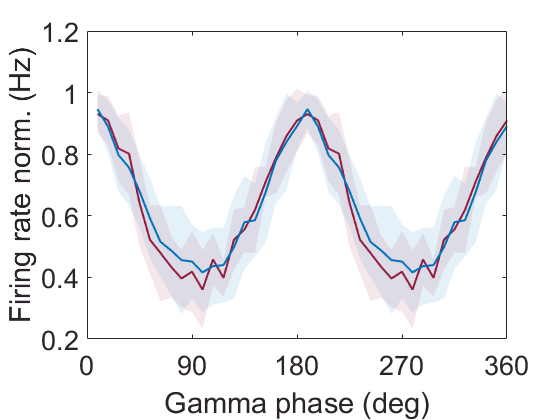

figure;
for je=1:5
    NGF_gammaNorm(je,:) = NGF_theta{je+24, 45:64}./max(NGF_theta{je+24, 45:64});
end

stdshade([NGF_gammaNorm NGF_gammaNorm], 0.1, [0.6350 0.0780 0.1840]);

hold on

for je=6:23
    NGFput_gammaNorm(je-5,:) = NGF_theta{je+24, 45:64}./max(NGF_theta{je+24, 45:64});
end

stdshade([NGFput_gammaNorm NGFput_gammaNorm], 0.1, [0 0.4470 0.7410]);
xlabel ('Gamma phase (deg)'); ylabel ('Firing rate norm. (Hz)')
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',20)
xticks(0:10:80)
xticklabels(0:90:720)
hold off

NGF_slfs=readtable('NGF_fastgamma_slowgamma_coupling.xlsx');

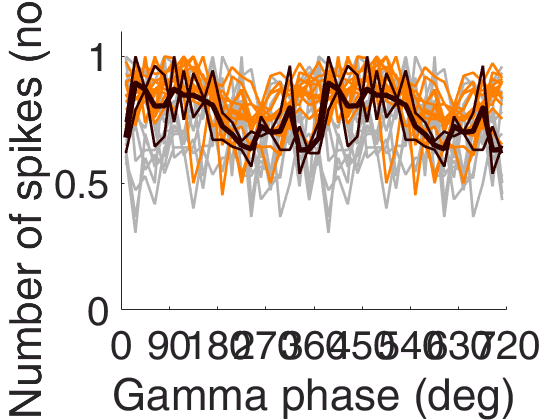

% Fast-gamma coupling for all identified (red) and putative (blue) neurogliaform cells
figure;
signID=find(NGF_slfs{:,27}<0.05 & NGF_slfs{:,24}>200);
NumUn=0;
NumPut=0;
NumId=0;
for je=setdiff(25:47, signID)
    line([gmbins gmbins+360], repmat((NGF_slfs{je, 3:22}./max(NGF_slfs{je, 3:22})),1,2), 'linewidth', 2, 'Color', [0.7 0.7 0.7]); %not significant
    hold on ; %gamma coupling of selected spikes
    NumUn=NumUn+1;
end
for je=intersect(30:47, signID)'
    line([gmbins gmbins+360], repmat((NGF_slfs{je, 3:22}./max(NGF_slfs{je, 3:22}, [], 2)),1,2), 'linewidth', 2, 'Color', [1 0.5 0]); %significant, putative
    hold on ; %gamma coupling of selected spikes
    NumPut=NumPut+1;
end
line ([gmbins gmbins+360], repmat(mean(NGF_slfs{intersect(30:47, signID), 3:22}./max(NGF_slfs{intersect(30:47, signID), 3:22}, [], 2)),1,2), 'LineWidth', 4, 'Color', [1 0.5 0]);
hold on
for je=intersect(25:29, signID)'
    line([gmbins gmbins+360], repmat((NGF_slfs{je, 3:22}./max(NGF_slfs{je, 3:22}, [], 2)),1,2), 'linewidth', 2, 'Color', [0.2 0 0]); %significant, identified
    hold on ; %gamma coupling of selected spikes
    NumId=NumId+1;
end
line ([gmbins gmbins+360], repmat(mean(NGF_slfs{intersect(25:29, signID), 3:22}./max(NGF_slfs{intersect(25:29, signID), 3:22}, [], 2)),1,2), 'LineWidth', 4, 'Color', [0.2 0 0]);
hold on


%x=[0:1:720]; y=(cosd(x+180)+1).*0.5; 
% line (x,y, 'Color', 'k', 'LineWidth', 2) % theta
%y=[0:0.1:1];
%axis ([0 720 0 1]);
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',30)
xlabel ('Gamma phase (deg)'); ylabel ('Number of spikes (norm.)')
%pozi=get(gca,'Position'); pozi=[pozi(1) pozi(2) 1.2*pozi(3) 1.2*pozi(4)]; set(gca,'Position',pozi)

xlim([0 720])
ylim([0 1.1])
set(gca, 'Clipping', 'off')

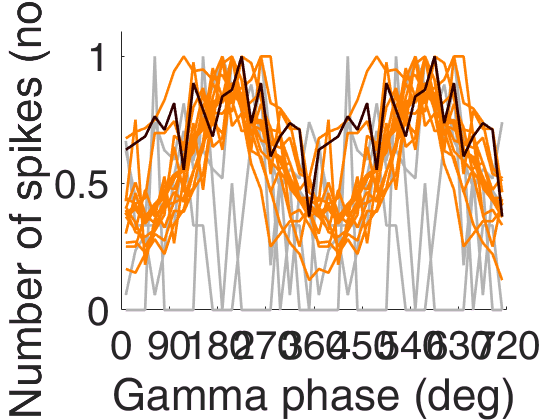

% Slow-gamma coupling for all identified (red) and putative (blue) neurogliaform cells
figure;
signID=find(NGF_slfs{:,53}<0.05 & NGF_slfs{:,50}>200);
NumUn=0;
NumPut=0;
NumId=0;
for je=setdiff(25:47, signID)
    line([gmbins gmbins+360], repmat((NGF_slfs{je, 29:48}./max(NGF_slfs{je, 29:48})),1,2), 'linewidth', 2, 'Color', [0.7 0.7 0.7]); %not significant
    hold on ; %gamma coupling of selected spikes
    NumUn=NumUn+1;
end
for je=intersect(30:47, signID)'
    line([gmbins gmbins+360], repmat((NGF_slfs{je, 29:48}./max(NGF_slfs{je, 29:48}, [], 2)),1,2), 'linewidth', 2, 'Color', [1 0.5 0]); %significant, putative
    hold on ; %gamma coupling of selected spikes
    NumPut=NumPut+1;
end
line ([gmbins gmbins+360], repmat(mean(NGF_slfs{intersect(30:47, signID), 29:48}./max(NGF_slfs{intersect(30:47, signID), 29:48}, [], 2)),1,2), 'LineWidth', 4, 'Color', [1 0.5 0]);
hold on
for je=intersect(25:29, signID)'
    line([gmbins gmbins+360], repmat((NGF_slfs{je, 29:48}./max(NGF_slfs{je, 29:48}, [], 2)),1,2), 'linewidth', 2, 'Color', [0.2 0 0]); %significant, identified
    hold on ; %gamma coupling of selected spikes
    NumId=NumId+1;
end
%line ([gmbins gmbins+360], repmat(mean(NGF_slfs{intersect(25:29, signID), 29:48}./max(NGF_slfs{intersect(25:29, signID), 29:48}, [], 2)),1,2), 'LineWidth', 4, 'Color', [0.2 0 0]);
hold on


%x=[0:1:720]; y=(cosd(x+180)+1).*0.5; 
% line (x,y, 'Color', 'k', 'LineWidth', 2) % theta
%y=[0:0.1:1];
%axis ([0 720 0 1]);
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',30)
xlabel ('Gamma phase (deg)'); ylabel ('Number of spikes (norm.)')
%pozi=get(gca,'Position'); pozi=[pozi(1) pozi(2) 1.2*pozi(3) 1.2*pozi(4)]; set(gca,'Position',pozi)

xlim([0 720])
ylim([0 1.1])
set(gca, 'Clipping', 'off')